# **2.17**

A discrete-time system is described by the following difference equation

**y[n] = 1.15y[n − 1] − 1.5y[n − 2] + 0.7y[n − 3] − 0.25y[n − 4] + 0.18x[n] + 0.1x[n − 1] + 0.3x[n − 2] + 0.1x[n − 3] + 0.18x[n − 4]**

with zero initial conditions.

a = [1 -1.15 1.5 -0.7 0.25];
b = [0.18 0.1 0.3 0.1 0.18];
n = [0:100];

(a) Compute and plot the impulse response h[n], 0 ≤ n ≤ 100 using the function  

**h=impz(b,a,N)**.

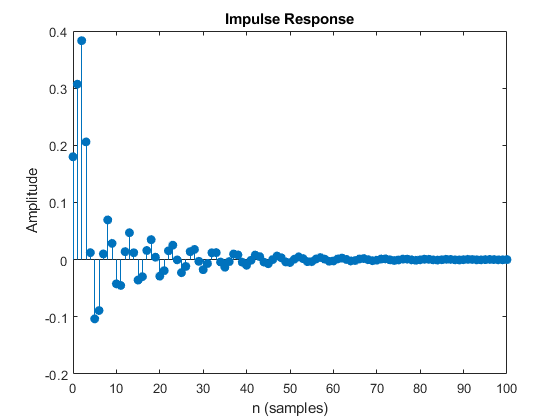

h = impz(b,a,length(n));
impz(b,a,length(n))

(b) Compute and plot the output y[n], if x[n] = u[n], 0 ≤ n ≤ 100 using the function

**y=filter(b,a,x)**.

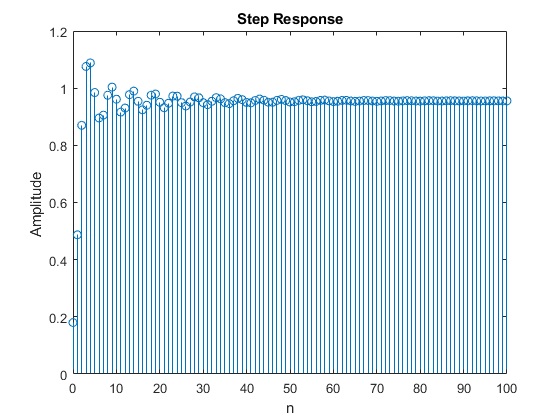

y = filter(b,a,ones(1,length(n)));
stem(n,y)
title('Step Response') ; xlabel('n') ; ylabel('Amplitude ')

(c) Compute and plot the output y[n], if x[n] = u[n], 0 ≤ n ≤ 100 using the function

**y=conv(h,x).**

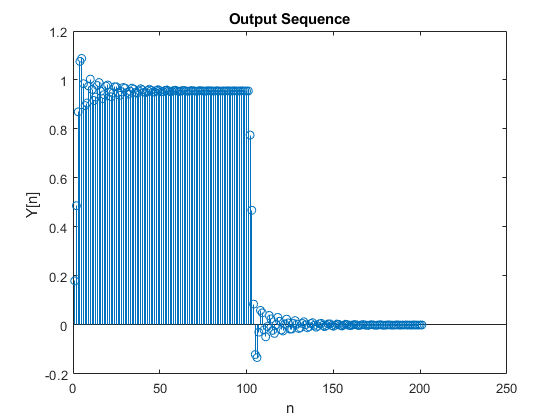

y = conv(h,ones(1,length(n)));
stem(y) 
title('Output Sequence') ; xlabel('n') ; ylabel('Y[n] ')

(d) Compute and plot the output y[n], if x[n] = u[n], 0 ≤ n ≤ 100 using the function

**y=filter(h,1,x)**

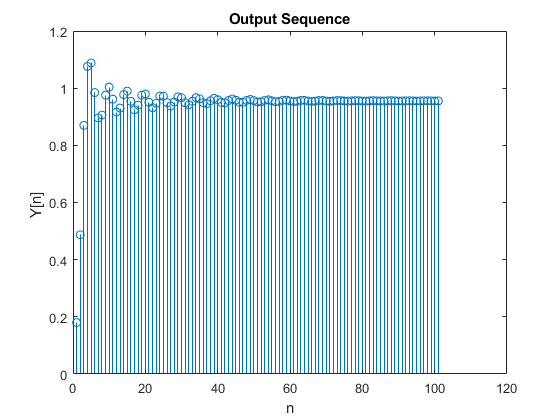

y = filter(h,1,ones(1,length(n)));
stem(y) 
title('Output Sequence') ; xlabel('n') ; ylabel('Y[n] ')

Part A gives the Impulse Response of the System

Part B gives the Step Response of the System

Part C by convolving gives both the Step and Impulse Response of the system

Part D gives the Zero State Response of the System, this mean the response of the system when initial conditions are set to Zero which is ame as Step Response of the System.